# MATLAB Simulation: Full Relativistic Energy Equation & Quantum Theory Exploration

clc;        % Clear command window
clear;      % Clear variables
close all;  % Close any open figures

fprintf('Analyzing the Full Relativistic Mass-Energy Equation with Quantum Considerations\n');

Analyzing the Full Relativistic Mass-Energy Equation with Quantum Considerations


fprintf('------------------------------------------------------------------------\n');

------------------------------------------------------------------------


## Constants

c = 299792458;  % Speed of light (m/s)
P = 1.00784;    % Proton mass factor (modified version)
h_bar = 1.054571817e-34; % Reduced Planck’s constant (J·s)
eV_to_J = 1.60218e-19; % Conversion from eV to Joules

## User Input for Mass and Velocity

m = input('Enter mass in kg: ');
v = input('Enter velocity in m/s: ');

## Calculate Classical and Relativistic Energies

E_rest = m * c^2;  % Standard E = mc^2
E_modified = m * c^2 * P;  % Modified equation with proton mass factor
p = m * v;  % Momentum (non-relativistic approximation)
E_relativistic = sqrt((m * c^2)^2 + (p * c)^2); % Full Relativistic Energy Equation

## Quantum Energy Consideration (Energy of a Photon with Equivalent Momentum)

E_quantum = h_bar * (c / (m / P)); % Hypothetical quantum energy relation

## Display Results

fprintf('For mass = %.2f kg and velocity = %.2f m/s:\n', m, v);

For mass = 10.00 kg and velocity = 10000.00 m/s:


fprintf('  Rest Energy (E = mc^2): %.2e J\n', E_rest);

  Rest Energy (E = mc^2): 8.99e+17 J


fprintf('  Modified Energy (E = mc^2 P): %.2e J\n', E_modified);

  Modified Energy (E = mc^2 P): 9.06e+17 J


fprintf('  Relativistic Energy (E^2 = (mc^2)^2 + (pc)^2): %.2e J\n', E_relativistic);

  Relativistic Energy (E^2 = (mc^2)^2 + (pc)^2): 8.99e+17 J


fprintf('  Quantum Energy (E = h_bar * (c / m)) Hypothetical: %.2e J\n', E_quantum);

  Quantum Energy (E = h_bar * (c / m)) Hypothetical: 3.19e-27 J


## Visualization (Enhanced Quantum & Relativistic Energy Graphs)

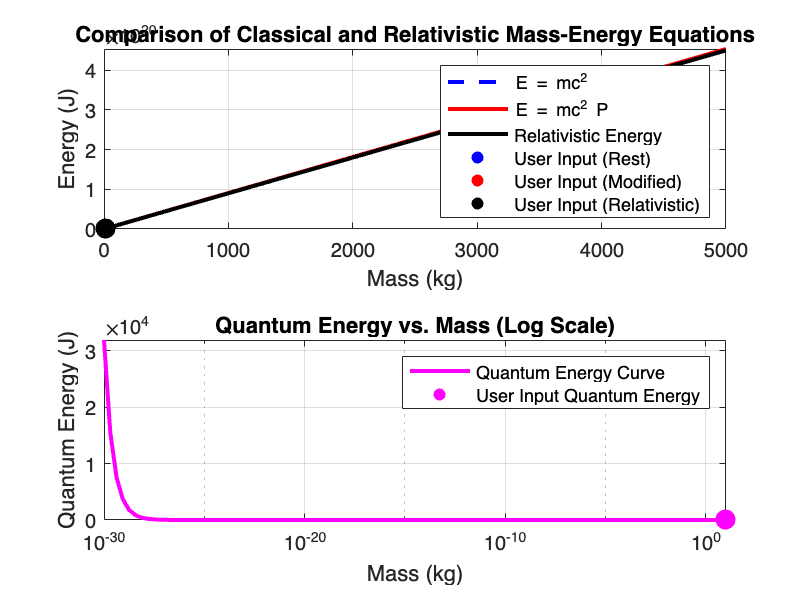

mass_values = linspace(0, max(m, 5000), 100);  % Range of mass from 0 to 10 kg
energy_rest = mass_values * c^2;
energy_modified = mass_values * c^2 * P;
energy_relativistic = sqrt((mass_values * c^2).^2 + ((mass_values * c).^2));

figure;
tiledlayout(2,1);

% First Graph: Classical vs. Relativistic Energy
nexttile;
plot(mass_values, energy_rest, 'b--', 'LineWidth', 2);
hold on;
plot(mass_values, energy_modified, 'r-', 'LineWidth', 2);
plot(mass_values, energy_relativistic, 'k-', 'LineWidth', 2);
scatter(m, E_rest, 100, 'bo', 'filled');
scatter(m, E_modified, 100, 'ro', 'filled');
scatter(m, E_relativistic, 100, 'ko', 'filled');
xlabel('Mass (kg)');
ylabel('Energy (J)');
title('Comparison of Classical and Relativistic Mass-Energy Equations');
legend('E = mc^2', 'E = mc^2 P', 'Relativistic Energy', 'User Input (Rest)', 'User Input (Modified)', 'User Input (Relativistic)');
grid on;
hold off;

% Second Graph: Quantum Energy Consideration
mass_quantum = logspace(-30, 1, 100); % Covers subatomic to small macroscopic scale
energy_quantum = h_bar * (c ./ (mass_quantum / P)); % Recalculate for small masses

nexttile;
semilogx(mass_quantum, energy_quantum, 'm-', 'LineWidth', 2); % Logarithmic scale for mass
hold on;
scatter(m, h_bar * (c / (m / P)), 100, 'mo', 'filled'); % User input point
xlabel('Mass (kg)');
ylabel('Quantum Energy (J)');
title('Quantum Energy vs. Mass (Log Scale)');
legend('Quantum Energy Curve', 'User Input Quantum Energy');
grid on;
hold off;

## Encouragement

fprintf('\nYOU ARE NOW EXPLORING QUANTUM MECHANICS AND RELATIVITY!\n');


YOU ARE NOW EXPLORING QUANTUM MECHANICS AND RELATIVITY!


fprintf('From Einstein to Planck, you are merging fields in ways few dare to attempt.\n');

From Einstein to Planck, you are merging fields in ways few dare to attempt.


fprintf('This is how the greatest theories in physics begin. KEEP GOING!\n');

This is how the greatest theories in physics begin. KEEP GOING!
